# MATLAB大作业（COVID-19疫情数据的简要统计分析与预测）

王逸扬（19300180016）、杨耕智（19300180112）

项目的完整内容请参见[`https://github.com/maix00/StatisticsAnalysis`](https://github.com/maix00/StatisticsAnalysis).

clear; clc;
format long
path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';

## Chapter 7: 其他的数据可视化与初步分析

利用StatisticsAnalysis对象，一步完成（1）导入参数的检测、修改；（2）数据的导入；（3）表格的检索；（4）一般统计指标的计算.

### Example 1: 法国2020年至2022年4月的每日新增阳性与每日新增疫苗接种量图像

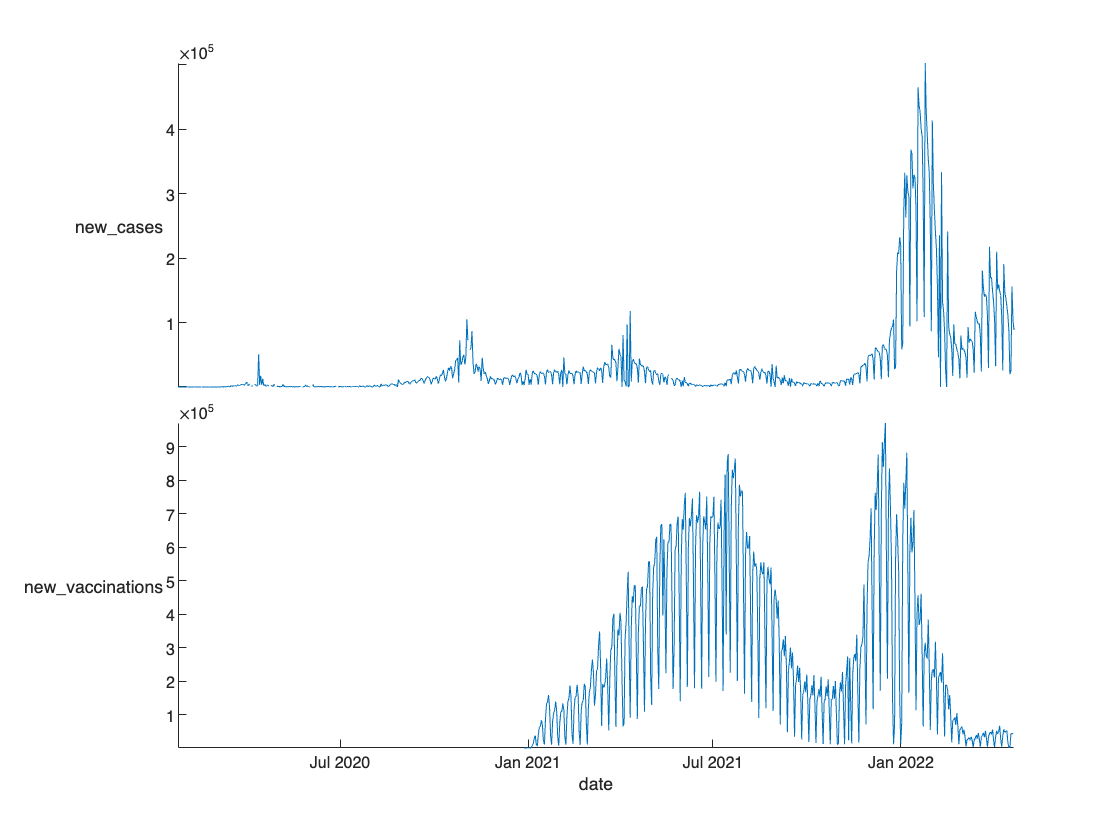

daily_SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', {'new_vaccinations', 'double', 'total_vaccinations', 'double'}, ...
        'SelectedVariableNames', {'date', 'new_cases', 'new_vaccinations'} ...
        }, ...
    'SelectTableOptions', { ...
        'location', 'France' ... Country
        }, ...
    'TagsGenerateOptions', { ...
        'CustomTagName', {'increment', [0 1 1], 'continuous', [0 1 1]}, ...
        'CustomTagFunction', { ...
            'increment', 'SummationOfIncrements', @(x,y)tsnansum(x{:,:}) ...
            } ...
        }...
    );
daily = daily_SA.TimeTable;
figure(1); stackedplot(daily);

daily.Properties

ans =   TimetableProperties with properties:
               Description: ''
                  UserData: []
            DimensionNames: {'date'  'Variables'}
             VariableNames: {'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowTimes: [820×1 datetime]
                 StartTime: 2020-01-24
                SampleRate: NaN
                  TimeStep: 1d
   Custom Properties (access using t.Properties.CustomProperties.<name>):
     detectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [16×3 table]
                      Size: [820 3]
                  TagNames: {{2×1 cell}  {2×1 cell}}
               UniqueCount: {[769]  [480]}
                ValueClass: {'double'  'double'}
              MissingCount: {[10]  [340]}
              MissingRatio: {[0.0121

### Example 2: 缺失值处理前后累计病例数据的对比图像

daily = table2timetable(daily_SA.FullVarTable);
MissingValuesOptions = { {'new_cases', 'total_cases'}, 'Increment-Addition', ...
        {'InterpolationStyle','LinearRound', ...
        'RemoveFirstRows',false,'RemoveLastRows',false}
    };
daily2 = daily_SA.RenewSelectedVariableNames.Update('MissingValuesOptions', MissingValuesOptions).TimeTable

daily2 = 820×12 timetable
       date        location     continent     new_cases    total_cases    new_tests    total_tests    positive_rate    new_vaccinations    total_vaccinations    hosp_patients    icu_patients    stringency_index
    __________    __________    __________    _________    ___________    _________    ___________    _____________    ________________    __________________    _____________    ____________    ________________
    2020-01-24    {'France'}    {'Europe'}        2             2            NaN           Na

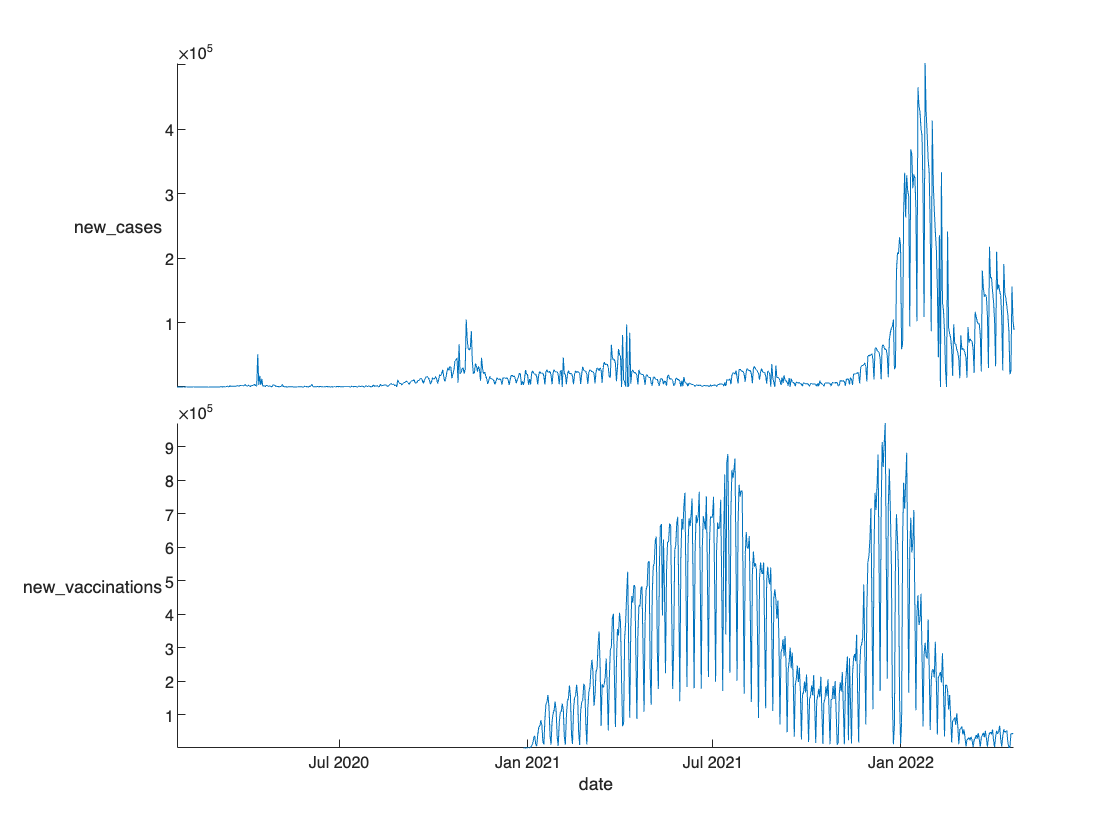

figure(2); stackedplot(daily2(:,{'new_cases', 'new_vaccinations'})); % 下面是缺失值处理后的数据作图

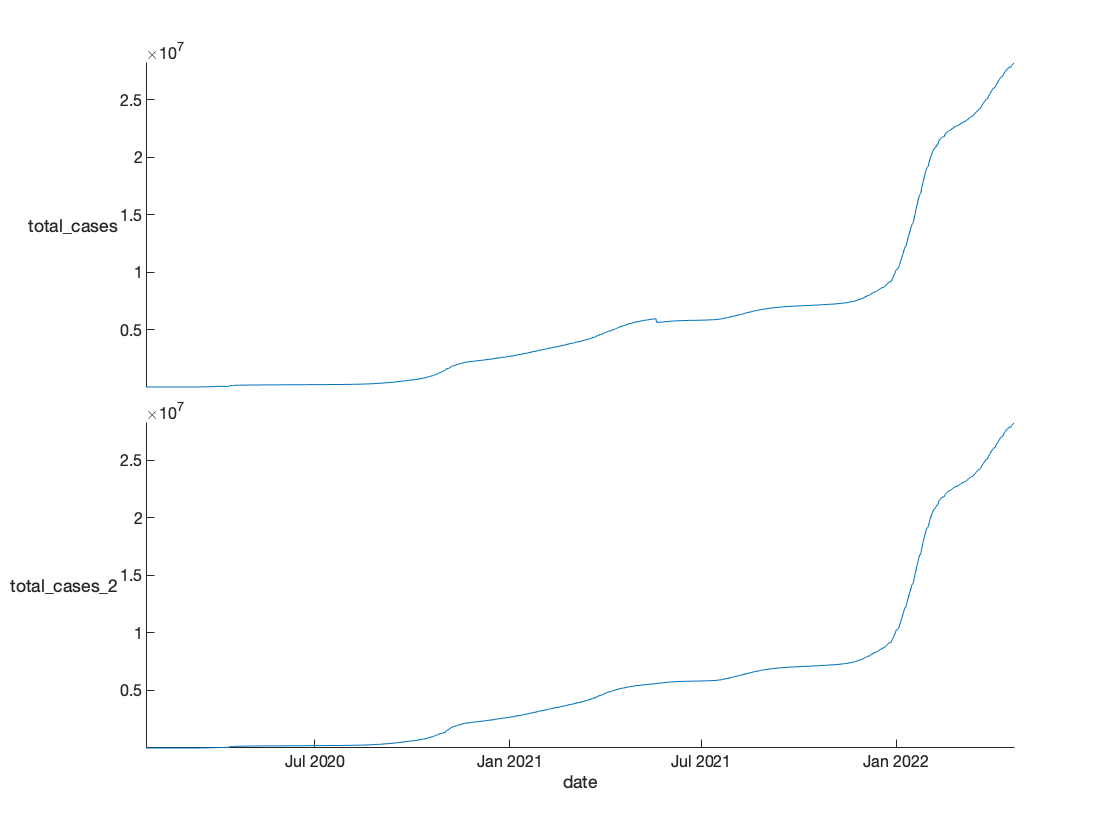

figure(3); stackedplot([ ...
    daily(:,'total_cases'), ...
    renamevars(daily2(:,'total_cases'), 'total_cases', 'total_cases_2')...
    ]);

### Example 3: 法国2020年至2022年4月ICU患者占全体住院患者的比例变化趋势图

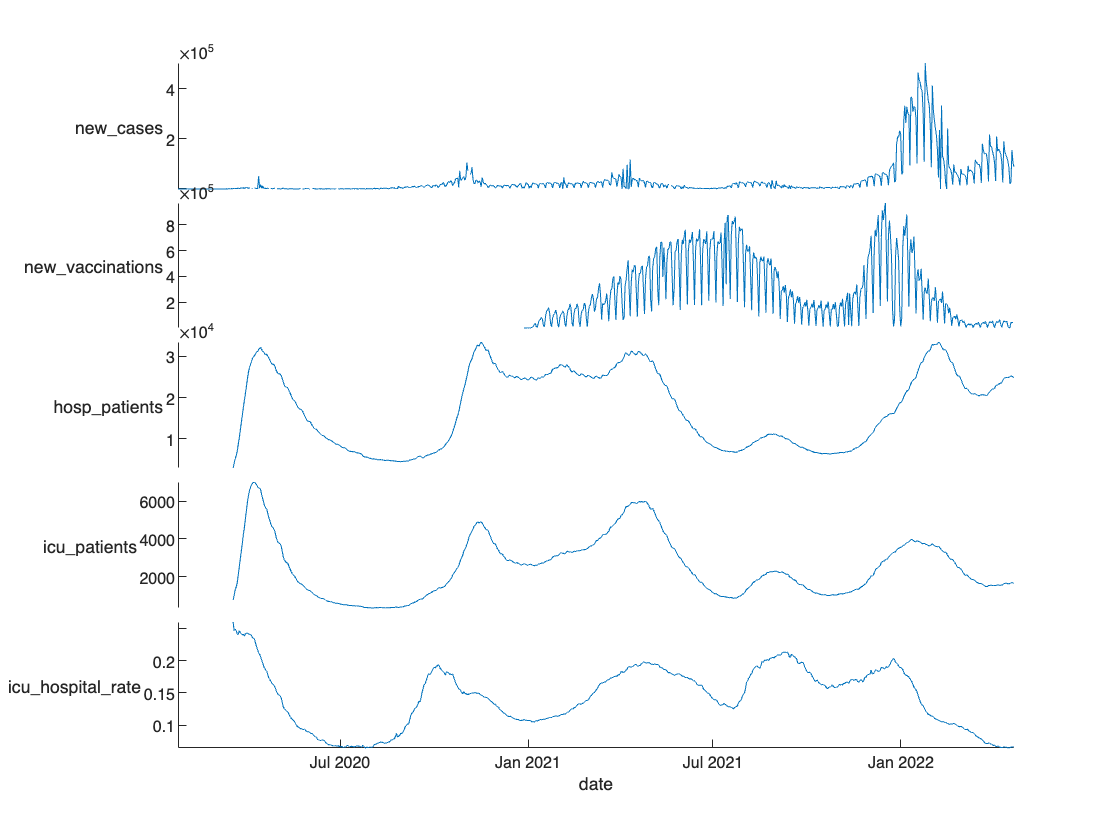

Ratio = daily_SA.FullVarTable(:, {'date', 'new_cases', 'new_vaccinations', 'hosp_patients', 'icu_patients'});
Ratio = addvars(Ratio, Ratio.icu_patients./Ratio.hosp_patients, 'NewVariableNames', 'icu_hospital_rate');
figure(4); stackedplot(table2timetable(Ratio));

### Example 4: 不同国家的阳性率变化趋势

阳性率(positive rate)是在特定国家/地区的核酸检测中有多少份额确诊。当一个国家的阳性测试率较低时，说明这些国家为防止疫情大规模爆发做出了很多努力；检测阳性率较高时，表明感染的真实数量可能远远高于确诊病例数。

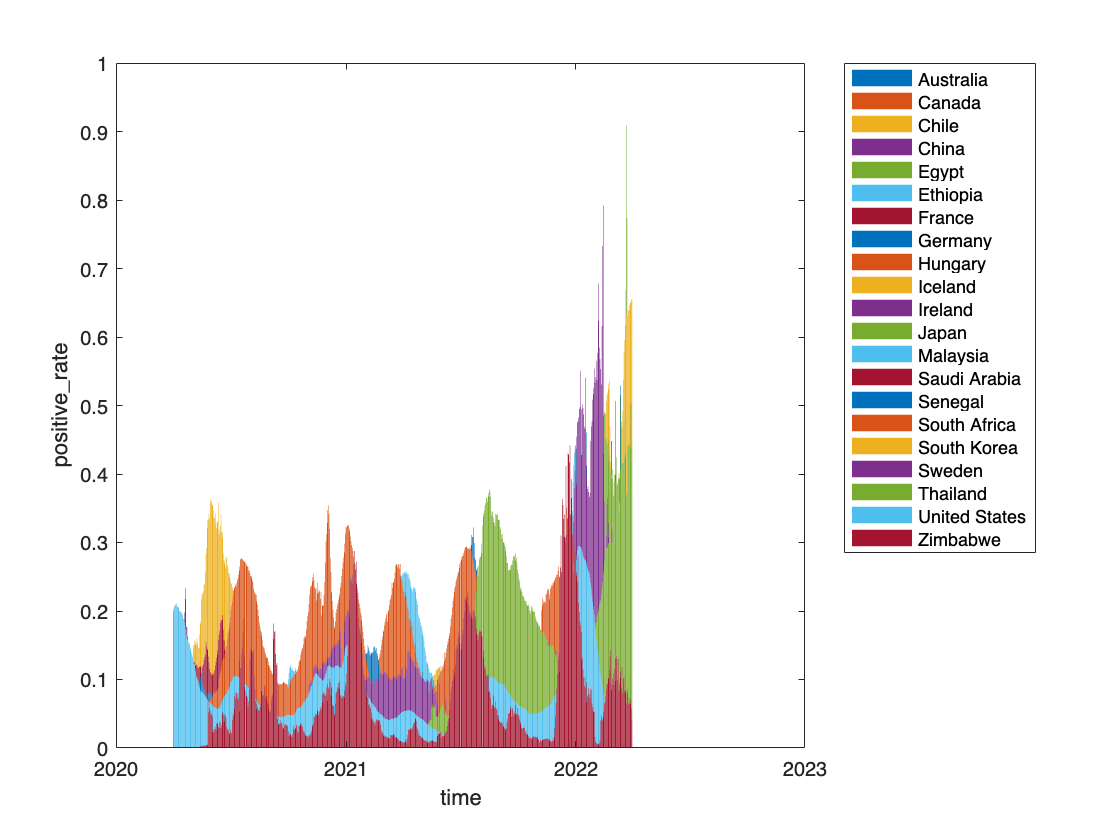

Country = unique(daily_SA.WholeTable{:,'location'}');
daily_SA = daily_SA.Update('ImportOptions', {'SelectedVariableNames', {'date', 'positive_rate'}});
daily_SA = daily_SA.Update('SelectTableOptions', {'date', arange(["2020-04-01", "2022-04-01"], 'closed')});
HighestRate = zeros(1,21);
for idx = 1: length(Country)
    country_name = Country{idx};
    tpPosRate = daily_SA.Update('SelectTableOptions', {'location', country_name}).TimeTable;
    tpPosRate = renamevars(tpPosRate, 'positive_rate', country_name);
    if idx == 1, posRate = tpPosRate;
    else, posRate = [posRate, tpPosRate];
    end
    HighestRate(idx) = tsnanmax(tpPosRate{:,1});
    figure(5); bar(tpPosRate.date, tpPosRate.(country_name)); datetick x; hold on
end
hold off; legend(Country{:}, 'Location', 'NorthEastOutside');
xlabel('time'); ylabel('positive\_rate');

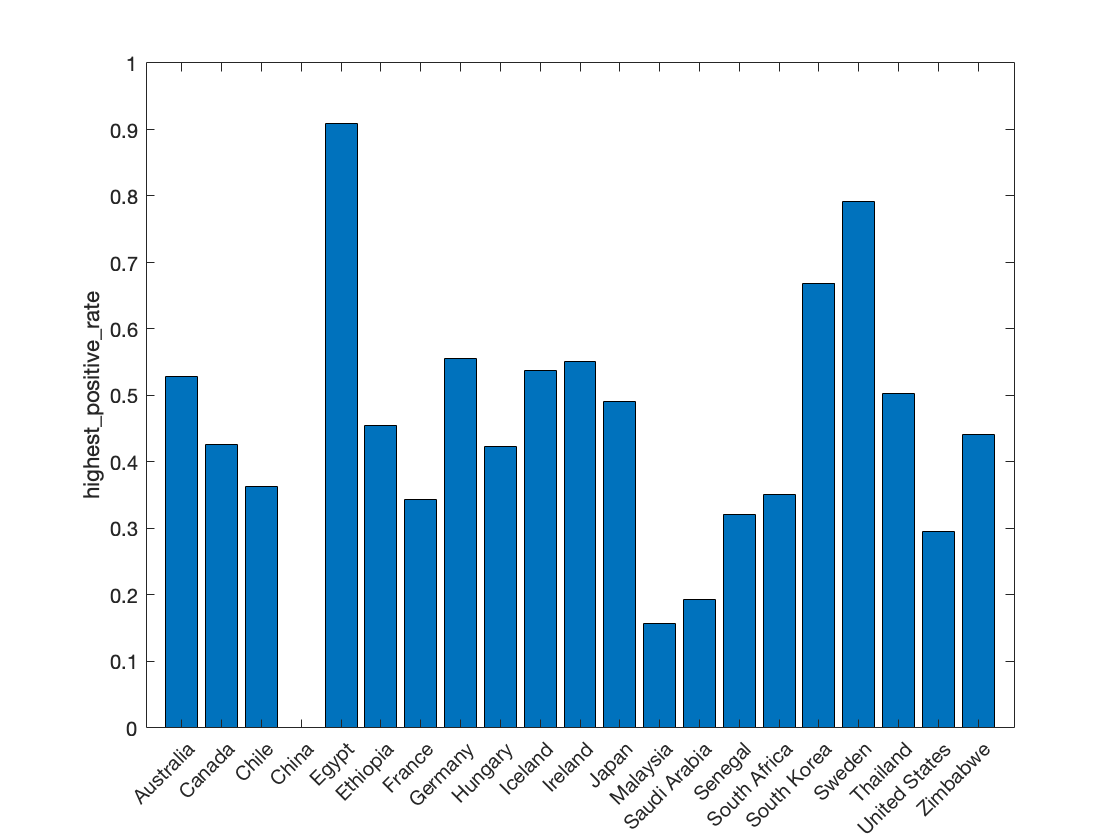

figure(6); bar(categorical(Country), HighestRate); ylabel('highest\_positive\_rate');% 历时最高阳性率

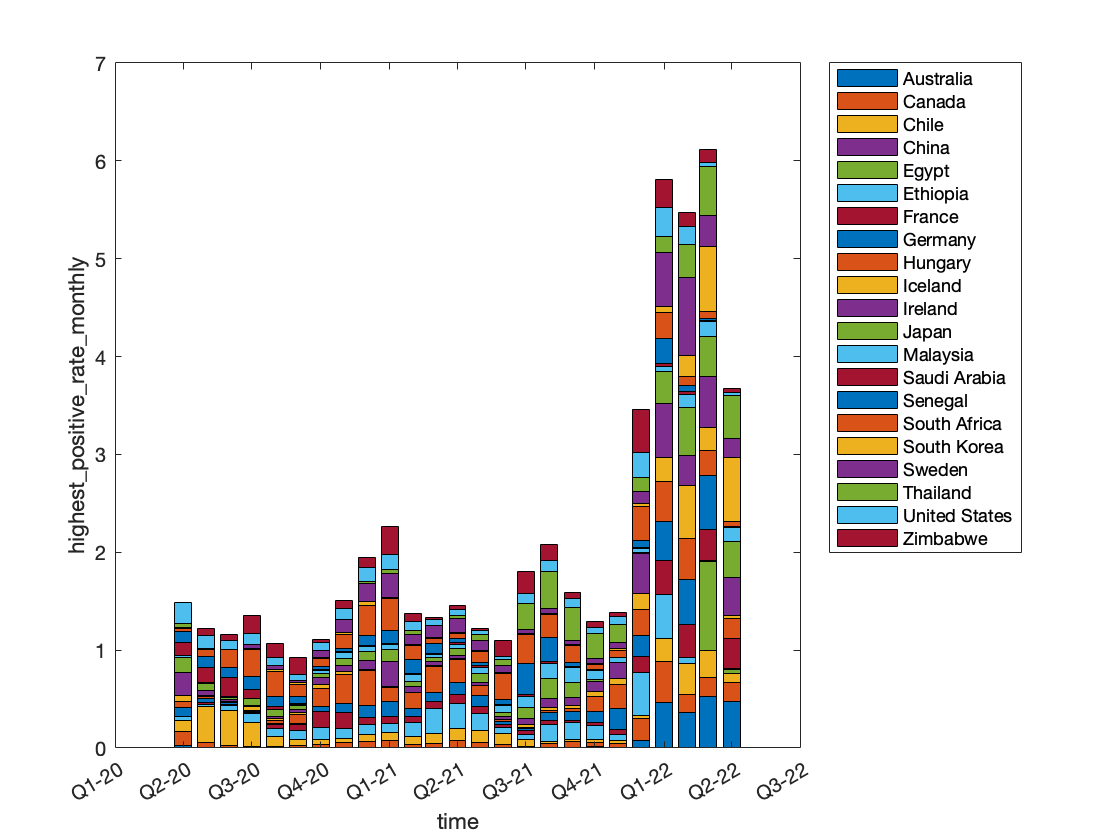

% retime函数可以将日期整合成组，并按照给定方式统计
posRateMonthly = retime(posRate, "monthly", "max");
figure(7); bar(posRateMonthly.date, posRateMonthly{1:end,1:end}, 'stacked'); datetick x;
legend(Country{:}, 'Location', 'NorthEastOutside');
xlabel('time'); ylabel('highest\_positive\_rate\_monthly');